# Plotting solution during the continuation procedure

Visualizing the solution during the continuation procedure is often mandatory. However, displaying curves can becomes time consuming and may requires a significant amount of time. In order to optimize the display, the `iterativeDisplay` toolbox is used. This toolbox is automatically installed with the continuation procedure toolbox.

What are the issue? Consider that the continuation procedure main loop may be executed hundreds of times. 

- plot update : instead of creating new graphic objects (plot, surface, etc) at every iteration, it is significantly faster to update theor properties `XData`, `YData`, etc. of the existing plot parameters

- displaying legends : axes legends consumes a lot of time during an update. So it is better to display them only once the algorithm is terminated.

The iterativeDisplay allows to manage all this optimization without modifying too much the way you are used to display graphics with matlab.

However, if you want, the `continuationProcedure` object will call the plotFigFcn with all the information needed to perform the graphics management using you own code.

## Displaying BVP or ODE solutions using plotFigFcn

The following section explain how to write the `plotFigFcn` function.

function dataPlot=plotFigFcn(dataPlot,status,id, sol,continuationParams,fixedParams,str)

`dataPlot` is a structure containing various information:

- `dataPlot.history.lambda` : array containing the $\lambda \;$values over the iterations

- `dataPlot.history.iterSuccess` : array containing a boolean flag indicating if the problem was solved

`dataPlot.history` may also contains other fields provided by the scheduler. If the `storeSolutionInHistory` parameter has been set during the creation of the continuation procedure object, then `dataPlot.history.solution` contains all the solutions over the continuation procedure iterations.

If needed, `dataPlot` can be used to save any information such as graphic object handle.

If needed, you can retrieve the parameters with the following code

retrieveContinuationParameters({continuationParams,fixedParams});

Then you simply need to add "`id.`" in front of every Matlab graphic command. Note that the `iterativeDisplay` does not support all of the Matlab graphic commands (cf the iterativeDisplay toolbox help, under the "Supplementary material" section).

A typical code will start by creating a figure. If you are using livescripts, it is highly advised to "undock" the figure from the script to achieve faster display. This is achieved by setting the "`visible`" property of the figure to true.

hFig=id.figure;
id.setOnce(hFig,'visible','on'); % Undock the figure

Then we will prepare a `tiledlayout` to split the figure into different axis. We save the handle to the `tiledlayout` into the variable `h`.

% Pepare a tiledlayout
h=id.tiledlayout(4,2);

The continuation procedure sends a string str with the iteration number and current $\lambda$ value. We will use that as a title.

% Add a title with lambda value & iteration
h.Title.String=str;

Then we plot the different curves using the data in the solution. This will have to be adapted to your problem.

Note that the iterativeDisplay toolbox does not support to use syntax such as `grid on`. Instead, you must use a functional form `id.grid('on').`

id.nexttile(1);
id.plot(sol.x,sol.y(1,:));
id.hold('on');
id.plot(sol.x([1 end]),[x0 xT],'*');
id.legend('x');
id.title('State 1');
id.grid('on');
id.nexttile(3);
id.plot(sol.x,sol.y(2,:))
id.legend('p');
id.title('Co State 1');
id.grid('on');

id.nexttile(5);
id.plot(sol.x,sol.u);
id.title('Control');
id.legend('u');
id.grid('on');

The continuation procedure also provide a plotHistory function to display the history of the schedule parameters. You can also use an optional third parameters to select a linear plot ("`lin`") or semilogarithmic ("`log`").

id.nexttile([4 1]);
plotHistory(dataPlot,id);
id.grid('on');

Note that you do not have to worries about the status of the continuation procedure, as it will sets the `iterativeDisplay` object `id` in the correct state before calling  `plotFigFcn`.

The outcome is a figure with the following layout that is quickly updated at each iteration.

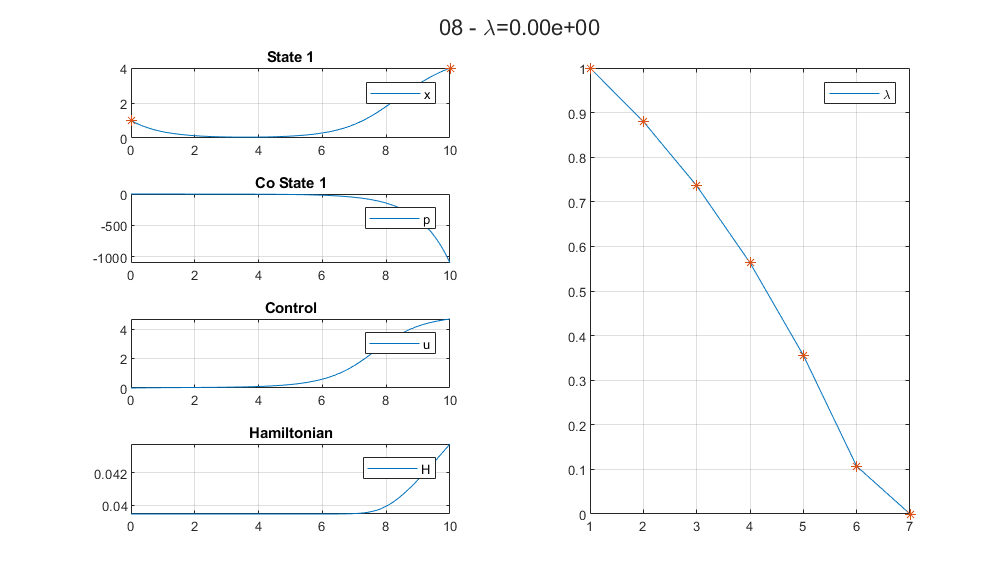

## Plotting solution with custom code

function dataPlot=plotFigFcn(dataPlot,status,id, sol,continuationParams,fixedParams,str)

The continuation procedure will call the provided `plotFigFcn` at every iteration. It receive a status parameter that to indicates the continuation procedure state : 1 for initializaton, 2 for algorithm iteration update and 3 for final update.

You may use `dataPlot` to store internal values such as handles of the created graphic objects.

A typical code would create the graphics object (figure, subplot, plot, surface, etc) when `status==1`.

It would then update the objects properties (`XData`, `YData`, etc) when `status==2.`

Finallaly, it would displays the legends only during the final iteration, when `status==3`.